SVG = loadsvg("bird.svg",0.1,false);%building.svg

%imread("bird.svg");
length(SVG{1})

ans = 660

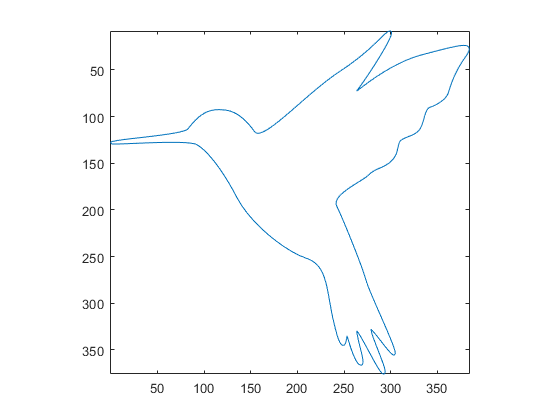

figure
plot(SVG{1}(:,1),SVG{1}(:,2))
axis image equal
set(gca,"YDir","reverse")


img = imread("HighNote.jpg");
img_bw = img(:,:,1) < 127;
B=bwboundaries(img_bw,8)%'noholes'

B = 4×1 cell array
    {1390×2 double}
    { 695×2 double}
    { 293×2 double}
    { 241×2 double}


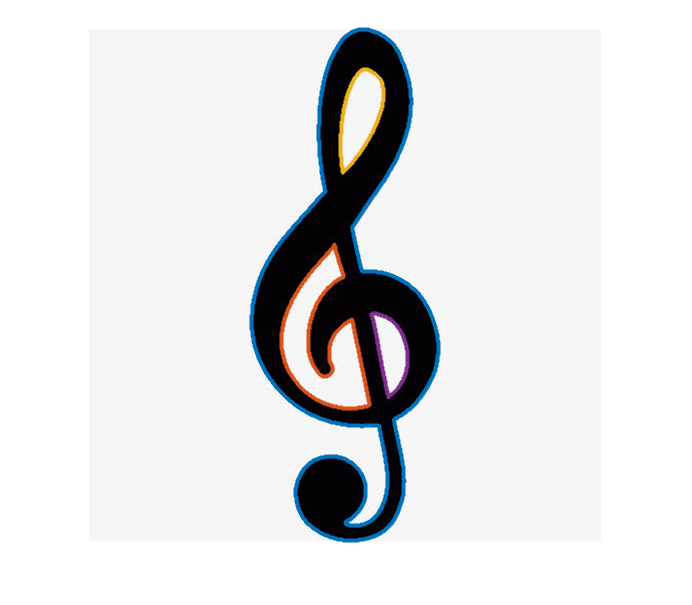

figure
imshow(img)
hold on 
for Bdr_i=1:length(B)
plot(B{Bdr_i}(:,2),B{Bdr_i}(:,1),"LineWidth",3)
end

save("HighNoteBdr.mat", "B")

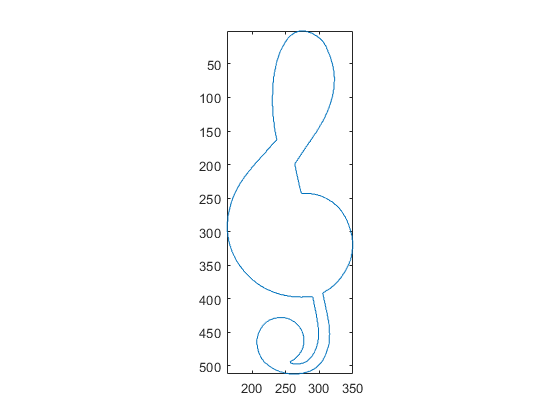

Xcoor = B{1}(:,2);
Ycoor = B{1}(:,1);
Zcoor = Xcoor + j * Ycoor;

figure
plot(Xcoor,Ycoor)
axis image equal
set(gca,"YDir","reverse")

Ucoef = fft(Zcoor);
UAmp = abs(Ucoef);
UAng = angle(Ucoef);
figure
subplot(211)
plot(UAmp(2:end-1))
subplot(212)
plot(UAng(2:end-1))

cos(UAng(2:end) + theta)

ans =    -0.9796   -0.9794   -0.9793   -0.9791   -0.9790   -0.9788   -0.9787   -0.9785   -0.9784   -0.9782   -0.9781   -0.9779   -0.9778   -0.9776   -0.9775   -0.9773   -0.9772   -0.9770   -0.9769   -0.9767   -0.9766   -0.9764   -0.9762   -0.9761   -0.9759   -0.9758   -0.9756   -0.9755   -0.9753   -0.9751   -0.9750   -0.9748   -0.9747   -0.9745   -0.9743   -0.9742   -0.9740   -0.9739   -0.9737   -0.9735   -0.9734   -0.9732   -0.9730   -0.9729   -0.9727   -0.9725   -0.9724   -0.9722   -0.9720   -0.9719
   -0.3631   -0.3637   -0.3644   -0.3651   -0.3657   -0.3664   -0.3671   -0.3677   -0.3684   -0.3691   -0.3697   -0.3704   -0.3711   -0.3718   -0.3724   -0.3731   -0.3738   -0.3744   -0.3751   -0.3758   -0.3764   -0.3771   -0.3778   -0.3784   -0.3791   -0.3798   -0.3804   -0.3811   -0.3817   -0.3824   -0.3831   -0.3837   -0.3844   -0.3851   -0.3857   -0.3864   -0.3871   -0.3877   -0.3884   -0.3891   -0.3897   -0.3904   -0.3910   -0.3917   -0.3924   -0.3930   -0.3937   -0.3943   -0.3950   

cos(UAng(10:50) + theta)

ans =     0.9493    0.9490    0.9488    0.9486    0.9483    0.9481    0.9479    0.9477    0.9474    0.9472    0.9470    0.9467    0.9465    0.9463    0.9460    0.9458    0.9456    0.9453    0.9451    0.9449    0.9446    0.9444    0.9442    0.9439    0.9437    0.9434    0.9432    0.9430    0.9427    0.9425    0.9422    0.9420    0.9418    0.9415    0.9413    0.9410    0.9408    0.9405    0.9403    0.9401    0.9398    0.9396    0.9393    0.9391    0.9388    0.9386    0.9383    0.9381    0.9378    0.9376
   -0.9857   -0.9858   -0.9860   -0.9861   -0.9862   -0.9863   -0.9864   -0.9865   -0.9867   -0.9868   -0.9869   -0.9870   -0.9871   -0.9872   -0.9874   -0.9875   -0.9876   -0.9877   -0.9878   -0.9879   -0.9880   -0.9881   -0.9883   -0.9884   -0.9885   -0.9886   -0.9887   -0.9888   -0.9889   -0.9890   -0.9891   -0.9892   -0.9893   -0.9894   -0.9895   -0.9896   -0.9897   -0.9898   -0.9899   -0.9900   -0.9902   -0.9903   -0.9904   -0.9905   -0.9905   -0.9906   -0.9907   -0.9908   -0.9909   

UAmp(10:50).*cos(UAng(10:50) + theta)

ans = 	1.0e+03 *

    1.7124    1.7120    1.7116    1.7112    1.7108    1.7103    1.7099    1.7095    1.7091    1.7087    1.7083    1.7079    1.7074    1.7070    1.7066    1.7062    1.7058    1.7053    1.7049    1.7045    1.7041    1.7036    1.7032    1.7028    1.7023    1.7019    1.7015    1.7011    1.7006    1.7002    1.6998    1.6993    1.6989    1.6984    1.6980    1.6976    1.6971    1.6967    1.6962    1.6958    1.6954    1.6949    1.6945    1.6940    1.6936    1.6931    1.6927    1.6922    1.6918    1.6913
   -1.8343   -1.8346   -1.8348   -1.8350   -1.8352   -1.8354   -1.8357   -1.8359   -1.8361   -1.8363   -1.8365   -1.8368   -1.8370   -1.8372   -1.8374   -1.8376   -1.8378   -1.8380   -1.8382   -1.8384   -1.8387   -1.8389   -1.8391   -1.8393   -1.8395   -1.8397   -1.8399   -1.8401   -1.8403   -1.8405   -1.8407   -1.8409   -1.8411   -1.8413   -1.8414   -1.8416   -1.8418   -1.8420   -1.8422   -1.8424   -1.8426   -1.8428   -1.8430   -1.8431   -1.8433   -1.8435   -1.8437   -1.8439 

freq*theta

ans = 	1.0e+03 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000 

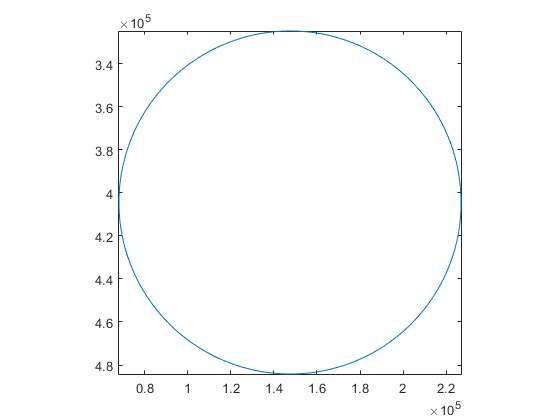

theta = [0:0.01:2*pi];
freq = [0:length(UAmp)-1]'/length(UAmp);
Xfit = sum(UAmp(1:end).*cos(UAng(1:end) - freq*theta),1);
Yfit = sum(UAmp(1:end).*sin(UAng(1:end) - freq*theta),1);
figure
plot(Xfit,Yfit)
axis image equal
set(gca,"YDir","reverse")

freq = [0:length(UAmp)-1]'/length(UAmp);
Zfit = sum(Ucoef .* exp(j*2*pi*freq*[1:length(UAmp)]),1)/length(UAmp)

Zfit = 	1.0e+02 *

   1.6400 + 2.8500i   1.6400 + 2.8400i   1.6400 + 2.8300i   1.6400 + 2.8200i   1.6400 + 2.8100i   1.6400 + 2.8000i   1.6400 + 2.7900i   1.6400 + 2.7800i   1.6400 + 2.7700i   1.6400 + 2.7600i   1.6500 + 2.7500i   1.6500 + 2.7400i   1.6500 + 2.7300i   1.6500 + 2.7200i   1.6500 + 2.7100i   1.6600 + 2.7000i   1.6600 + 2.6900i   1.6600 + 2.6800i   1.6600 + 2.6700i   1.6700 + 2.6600i   1.6700 + 2.6500i   1.6700 + 2.6400i   1.6700 + 2.6300i   1.6800 + 2.6200i   1.6800 + 2.6100i   1.6800 + 2.6000i   1.6800 + 2.5900i   1.6900 + 2.5800i   1.6900 + 2.5700i   1.6900 + 2.5600i   1.7000 + 2.5500i   1.7000 + 2.5400i   1.7000 + 2.5300i   1.7100 + 2.5200i   1.7100 + 2.5100i   1.7100 + 2.5000i   1.7200 + 2.4900i   1.7200 + 2.4800i   1.7300 + 2.4700i   1.7300 + 2.4600i   1.7300 + 2.4500i   1.7400 + 2.4400i   1.7400 + 2.4300i   1.7500 + 2.4200i   1.7500 + 2.4100i   1.7600 + 2.4000i   1.7600 + 2.3900i   1.7700 + 2.3800i   1.7700 + 2.3700i   1.7800 + 2.3600i


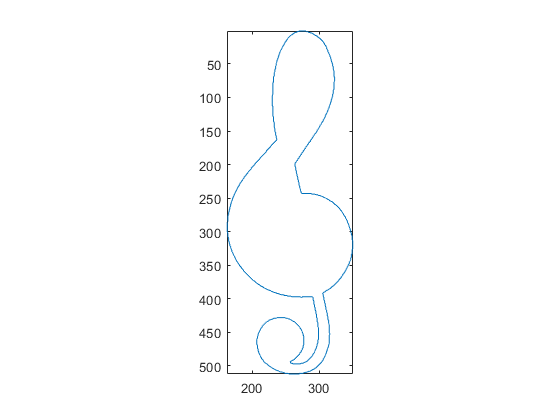

Xfit = real(Zfit);
Yfit = imag(Zfit);
figure
plot(Xfit,Yfit)
axis image equal
set(gca,"YDir","reverse")

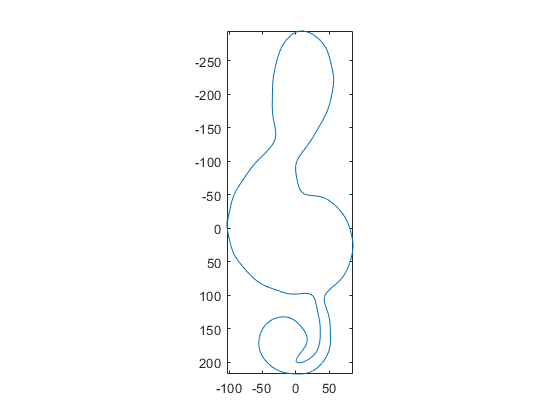

comp_n = 30;
FFTidx = [2:comp_n + 1,1390-comp_n+1:1390];
%1/length(UAmp)
theta = [0:7.1942e-04:1];%[0:length(UAmp)-1]/length(UAmp);%[0:0.001:1]%
freq = [0:length(UAmp)-1]';
Xfit = sum(UAmp(FFTidx) .* cos(2*pi*freq(FFTidx) * theta + UAng(FFTidx)), 1)/length(UAmp);
Yfit = sum(UAmp(FFTidx) .* sin(2*pi*freq(FFTidx) * theta + UAng(FFTidx)), 1)/length(UAmp);
figure
plot(Xfit,Yfit)
axis image equal
set(gca,"YDir","reverse")

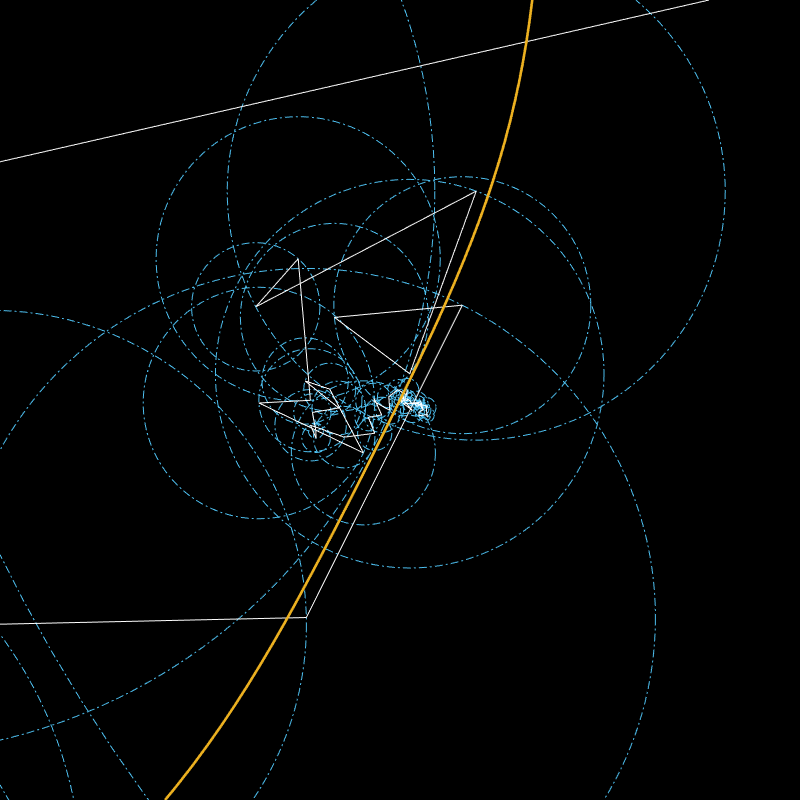

% More efficient version of it! 
N = length(UAmp);
window_W = 20;
comp_n = 40;
idxes = reshape([2:comp_n+1;N+1-[1:comp_n]],1,[]); % select the index of component
figure("Position",[0,0,800,800]);%axis equal;set(gca,"YDir","reverse")
z_store = [];
v = VideoWriter('FFT_anime.avi','Motion JPEG AVI');
v.FrameRate = 15;open(v);
%Frms = {};Fi=1;
for t = 0.5:1/N:1.5
cla;hold on;axis equal;set(gca,"YDir","reverse");xticks([]);yticks([]);%axis off;
set(gca,'Color','k','position',[0 0 1 1],'units','normalized')
%plot(Xfit,Yfit,"LineWidth",2,"Color","black");
z_displ = Ucoef(idxes).*exp(1i*2*pi*t*freq(idxes) )/N; % compute complex displacement vector
z_list = cumsum([0; z_displ]);zcur=z_list(end); % cum sum the 
z_store = [z_store, zcur]; 
% plot the epi circle
rads = UAmp(idxes);
drawCircles([real(z_list(1:end-1)),imag(z_list(1:end-1))], [rads]/N)
% viscircles([real(z_list(1:end-1)),imag(z_list(1:end-1))], [rads]/N,'Color',[0.3,0.3,0.3]);
% that is too slow
% Line plot ot arrow plot 
plot(real(z_list),imag(z_list),"LineWidth",0.75, 'Color', [1,1,1])
%quiver(real(z_list(1:end-1)),imag(z_list(1:end-1)),real(z_displ),imag(z_displ), 0, ...
%    'Color', [1,1,1],'MaxHeadSize',0.05)
plot(real(z_store),imag(z_store),"LineWidth",2, 'Color', [0.9290, 0.6940, 0.1250])
xlim(real(zcur) + [-window_W, window_W]);
ylim(imag(zcur) + [-window_W, window_W]);
drawnow
%Frms{fi}=getframe(gcf);fi=fi+1;
writeVideo(v,getframe(gcf))
%drawnow
end

close(v)

window_W = 20;
figure;%axis equal;set(gca,"YDir","reverse")

for t = 0.5:1/length(UAmp):1
cla;
%plot(Xfit,Yfit,"LineWidth",2,"Color","black");
hold on;axis equal;set(gca,"YDir","reverse");xticks([]);yticks([]);%axis off;
zcur = 0;
for comp_i=1:30
znext = zcur + Ucoef(1+comp_i)*exp(1i*2*pi*t*freq(1+comp_i) )/length(UAmp);%+ UAng(1+comp_i)
line([real(zcur),real(znext)],[imag(zcur),imag(znext)],"LineWidth",0.5)
zcur = znext;
znext = zcur + Ucoef(end-comp_i+1)*exp(1i*2*pi*t*freq(end-comp_i+1) )/length(UAmp);
line([real(zcur),real(znext)],[imag(zcur),imag(znext)],"LineWidth",0.5)
zcur = znext;
end
xlim(real(zcur) + [-window_W, window_W]);
ylim(imag(zcur) + [-window_W, window_W]);
set(gca,'Color','k')
drawnow
end



$$Z(t)=X(t)+Y(t)i$$



$$Z(t)=\sum_f A_f e^{i tf+\phi_f}=\sum_f A_f e^{i\phi_f} e^{ift}$$


As long as we have the coeeficients (Amplitude and phase) for different components it will be fine! 

%bwtraceboundary

img = imread("HighNote.jpg");
img_bw = img(:,:,1) < 127;
bw_bdr = bwperim(img_bw,8);
figure
imshow(bw_bdr)%bw_bdr(:,:,1))

function drawCircles(centers, radii, varargin)
thetaResolution = 2; 
theta=(0:thetaResolution:360)*pi/180;
x = radii*cos(theta)+centers(:,1);
x = cat(1,x',nan(1,length(radii)));
x = x(:);
y = radii*sin(theta)+centers(:,2);
y = cat(1,y',nan(1,length(radii)));
y = y(:);
line(x,y,'Color',[0.3010, 0.7450, 0.9330],"LineWidth",0.5,'LineStyle','-.')%[0, 0.2235, 0.3705]
% ...
%    'Color',options.Color, ...
%    'LineWidth',options.LineWidth, ...
%    'LineStyle',options.LineStyle);
end